# Simulating and Fitting Effort Discounting Models

Note: This script was run using MATLAB 2024b (versions 2023a or newer are probably okay)

If you are using an older version, you will need the combvec() function from the Deep Learning toolbox for part of the simulations below.

You will also need the Optimization toolbox to run this script (fmincon).

More information:

Wilson & Collins, 2019, *eLife *is an excellent resource for doing computational modelling.

Desmos graphing calculator is useful when developing models: [https://www.desmos.com/calculator](https://www.desmos.com/calculator)

Effort discounting online app: [https://sdn-lab.github.io/csc_app/](https://sdn-lab.github.io/csc_app/)

rng(03092025); % set randomizer seed

## Define and simulate model


$$SV = R - (E*k)$$


### Set up data to match pro-environmental effort experiment

reward = repmat(2:4, 1, 8)';
effort = repelem(2:5, 6)';

data = table(reward, effort);
data

data = 24×2 table
    reward    effort
    ______    ______

      2         2   
      3         2   
      4         2   
      2         2   
      3         2   
      4         2   
      2         3   
      3         3   
      4         3   
      2         3   
      3         3   
      4         3   
      2         4   
      3         4   
      4         4   
      2         4   


### Simulate choices using known discount (k) and beta parameters

% Fix parameters for simulating data
k_param_true = 0.5;
beta_param_true = 1;

% Define model formula
SV = reward - (effort .* k_param_true);


$$SV=reward-(effort*0.5)$$


data.SV = SV

data = 24×3 table
    reward    effort    SV 
    ______    ______    ___

      2         2         1
      3         2         2
      4         2         3
      2         2         1
      3         2         2
      4         2         3
      2         3       0.5
      3         3       1.5
      4         3       2.5
      2         3       0.5
      3         3       1.5
      4         3       2.5
      2         4         0
      3         4         1
      4         4         2
      2         4         0


### Calculate softmax

% (Predicted probabilities of choosing "work" option)
prob = exp(SV .* beta_param_true) ./ (exp(SV .* beta_param_true) + exp(1 .* beta_param_true));


$$\sigma(x_i) = \frac{exp(x_i)}{\sum^n_{j=1} exp(x_j)}$$



$$Pr(work) = \frac{exp(SV_{work}*\beta)}{exp(SV_{work}*\beta)+exp(1*\beta)}$$


### Simulate choices from probabilities

First generate a list of random numbers (0-1).

random_nums = rand(length(prob), 1);

Use them to 'simulate' choices.

choices = prob > random_nums;

data.prob       = prob;
data.random_num = random_nums;
data.choices    = choices;
data

data = 24×6 table
    reward    effort    SV      prob      random_num    choices
    ______    ______    ___    _______    __________    _______

      2         2         1        0.5     0.43203       true  
      3         2         2    0.73106     0.62752       true  
      4         2         3     0.8808     0.80572       true  
      2         2         1        0.5     0.53722       false 
      3         2         2    0.73106     0.12495       true  
      4         2         3     0.8808     0.60531       true  
      2         3       0.5    0.37754     0.19579       true  
      3         3       1.5    0.62246     0.12858       true  
      4         3       2.5    0.81757     0.64319       true  
      2         3       0.5    0.37754     0.27682       true  
      3  

Turn the above code into a function for use later.

## Fit model using Maximum Likelihood Estimation (MLE)

Using the simulated data above, fit the model using maximum likelihood estimation (MLE).

Can be used to check if "true" parameters can be recovered by the model.

% Will use `fmincon` to fit model
%
% [x, fval] = fmincon(fun,x0,[],[],[],[],lb,ub)
%
% Output:
%   x = solution (e.g., fitted params) to MLE fitting
%   fval = function value at solution (e.g., negative log-likelihood)
%
% Input: 
%   fun = function to minimize
%   x0 = initial starting points
%   lb = lower bounds of parameters being estimated
%   ub = upper bounds of parameters being estimated
%
% fitted_params = fmincon(model_function, starting_values,...,lower_bounds,upper_bounds)

recipient = repelem(["food", "climate"], 12)';
data.recipient = recipient;

First, create a function that `fmincon` will try to minimize.

Then see how well the 'true' parameters fit to the simulated data.

params = [k_param_true, beta_param_true];

negLL = fitModel(data, params); %(defined in "Functions" section at end of script)
fprintf('Minimised log-likelihood: %f', negLL);

Minimised log-likelihood: 12.504284

fitModel(data, [k_param_true, beta_param_true])

ans = 12.5043

fitModel(data, [3, 0.1])

ans = 18.3394

fitModel(data, [1.5, 2.5])

ans = 81.6094

#### Use `fmincon` to "guess" the true parameters

Functions like `fmincon` can be used to find parameters that minimize the function—i.e., minimize the (negative) log-likelihood.

Tries to "guess" which parameter values best explain the data—useful when the 'true' parameters are unknown!

The `fmincon` function allows you to set lower/upper bounds for the parameters it estimates.

% Set parameter bounds and initial values
lb = [0, 0];
ub = [2, 5];
fminoptions = optimoptions('fmincon','Display','off');

initial_params = rand(1, 2);

% Define input function for fmincon
inputfun = @(params) fitModel(data, params);

These give the same result:

fitModel(data, initial_params)

ans = 14.6153

inputfun(initial_params)

ans = 14.6153

% Fit model to minimizing function
[fit_params, negLL] = fmincon(inputfun, initial_params, ...
    [], [], [], [], ...
    lb, ub, ...
    [], fminoptions);

% Does the same thing:
%fmincon(@(params) fitModel(data, params), initial_params, ...);

% Fitted parameters and negative log-likelihood (negLL)
fprintf('k_param: %f\nbeta_param: %f', fit_params);

k_param: 0.517260
beta_param: 1.565915

Note: The fitted parameters may not exactly match the "true" parameters we set above.

With so few trials, the randomly simulated data may not perfectly reflect the "true" parameters.

One solution is to increase the number of simulated trials. Another solution is to simulate a wide range of "true" parameters many times to see how well the model can recover these parameters.

## Simulate range of parameters to check model robustness

Set a range of known k and beta values and simulate "participants" with these values.

### Simulate using a set range of parameter values

% Generate range of k and beta values
sim_k_values = 0 : 0.1 : 2; % min : increment : max
sim_beta_values =  0 : 0.25 : 5; % min : increment : max

% Create all combinations of these parameters
sim_params_allcombo = table2array(combinations(sim_k_values, sim_beta_values));
%sim_params_allcombo = combvec(sim_k_values, sim_beta_values)'; %combvec requires the Deep Learning toolbox

% Total number of "participants" to simulate,
% each with unique combination of k and beta "true" values
nsims = length(sim_params_allcombo);

fit_params = zeros(nsims, 2); %(preallocate array to improve speed)

% Loop through each combination of parameters
for isim = 1:length(sim_params_allcombo)
    true_k    = sim_params_allcombo(isim, 1);
    true_beta = sim_params_allcombo(isim, 2);

    % Generate simulated choices based on this combination of parameters
    sim_data = simulateData([true_k, true_beta]);

    % Fit the simulated data using MLE
    inputfun = @(params) fitModel(sim_data, params);
    initial_params = rand(1, 2);
    fit_params(isim, :) = fmincon(inputfun, ...
        initial_params, [], [], [], [], ...
        lb, ub, [], ...
        fminoptions);
end

Fitted k parameter vs. "True" k parameter

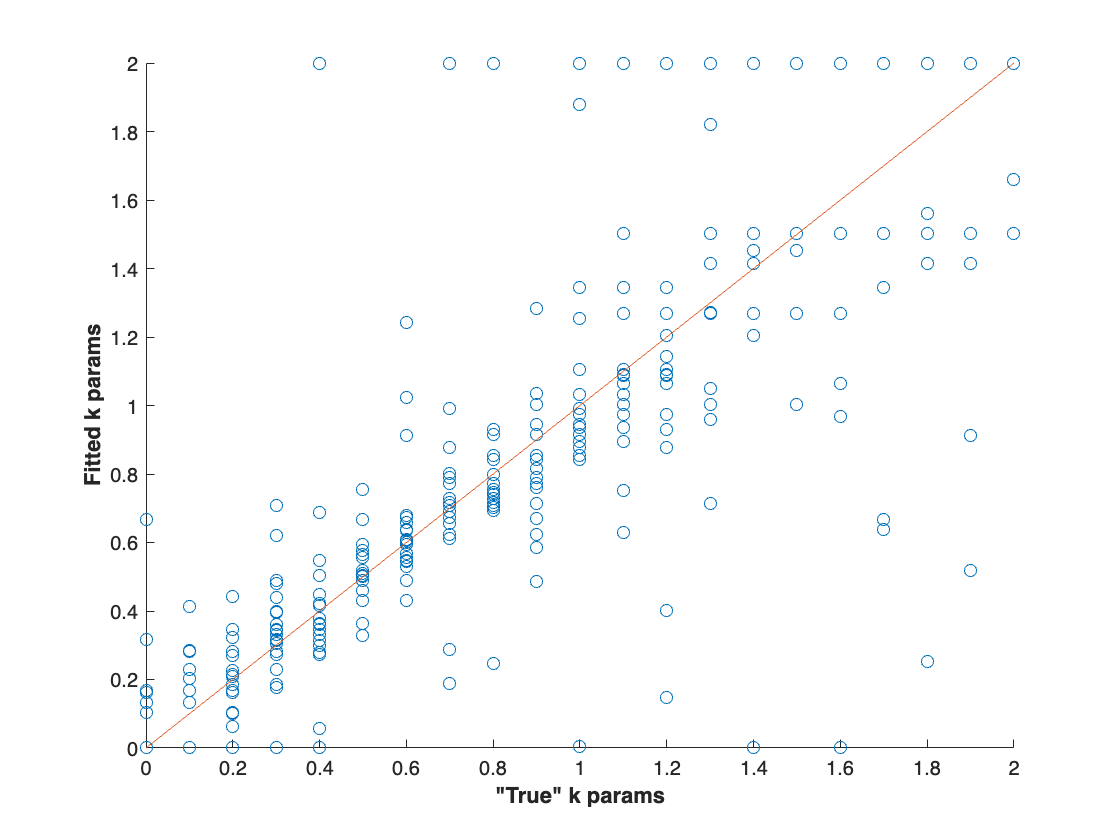

scatter(sim_params_allcombo(:,1), fit_params(:,1)); refline(1,0); xlabel('"True" k params', 'fontweight', 'bold'); ylabel('Fitted k params', 'fontweight', 'bold');

Fitted beta parameter vs. "True" beta parameter

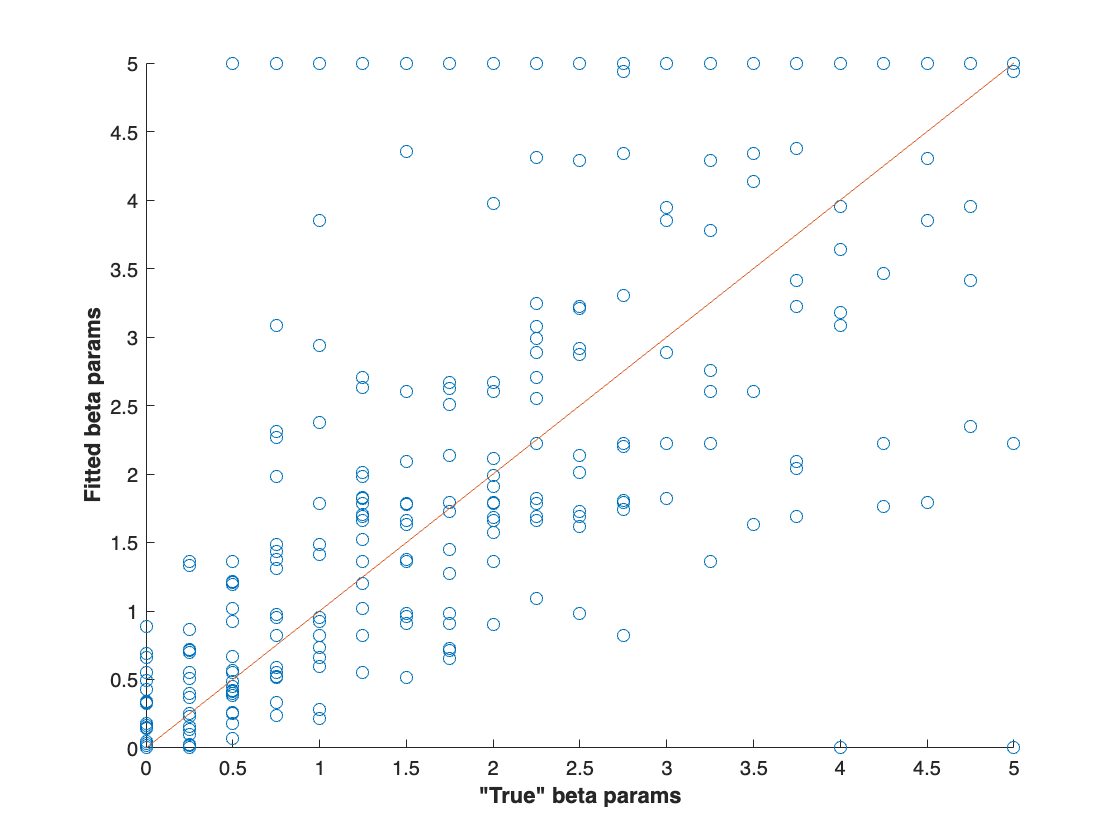

scatter(sim_params_allcombo(:,2), fit_params(:,2)); refline(1,0); xlabel('"True" beta params', 'fontweight', 'bold'); ylabel('Fitted beta params', 'fontweight', 'bold');

### Simulate using uniform distribution of parameter values

Rather than using predetermined `k` and `beta` values, we can generate a large number of values from a random distribution.

clear sim_data fit_params

nsims = 500; %number of "participants" to simulate

% Generate "true" k and beta values from random distribution
sim_k_values    = rand(1, nsims) * ub(1);
sim_beta_values = rand(1, nsims) * ub(2);

fit_params = zeros(nsims, 2); %(preallocate array to improve speed)

% Loop through each combination of parameters
for isim = 1:nsims
    true_k = sim_k_values(isim);
    true_beta = sim_beta_values(isim);

    % Generate simulated choices based on this combination of parameters
    sim_data = simulateData([true_k, true_beta]);

    % Fit the simulated data using MLE
    inputfun = @(params) fitModel(sim_data, params);
    initial_params = rand(1, 2);
    fit_params(isim, :) = fmincon(inputfun, ...
        initial_params, [], [], [], [], ...
        lb, ub, [], ...
        fminoptions);
end

Fitted k parameter vs. "True" k parameter

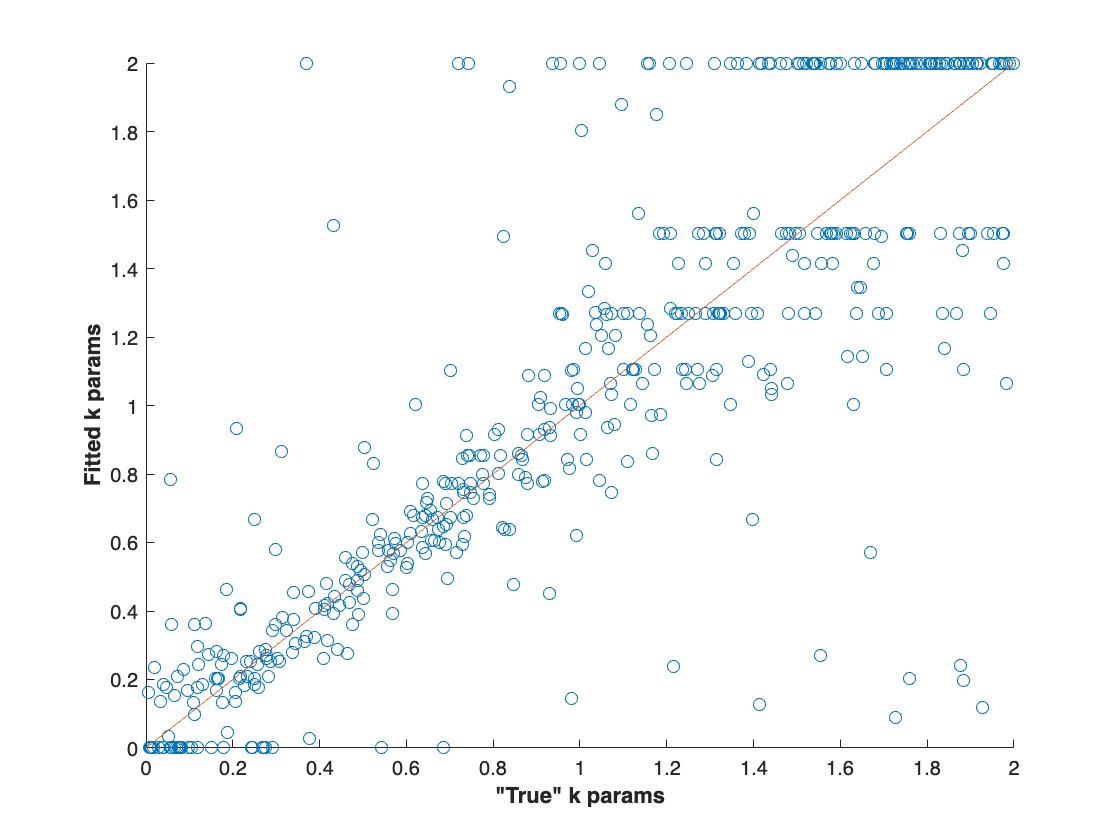

scatter(sim_k_values', fit_params(:,1)); refline(1,0); xlabel('"True" k params', 'fontweight', 'bold'); ylabel('Fitted k params', 'fontweight', 'bold');

Fitted beta parameter vs. "True" beta parameter

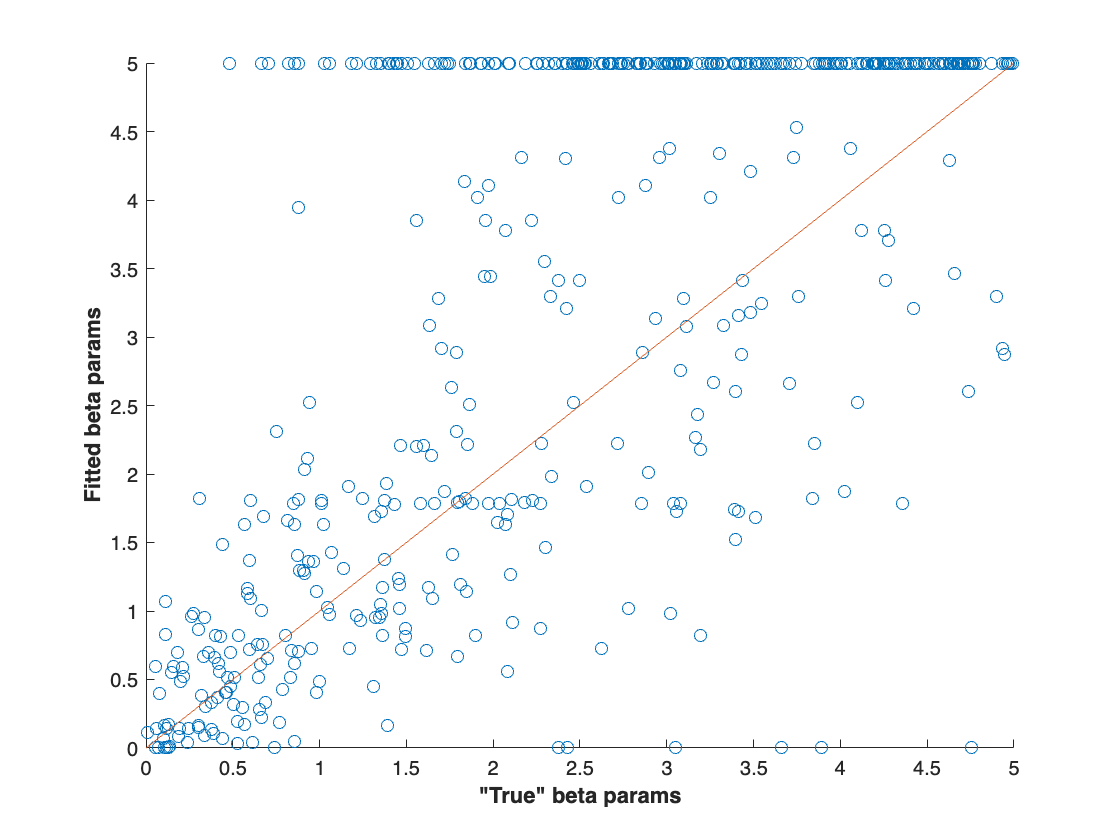

scatter(sim_beta_values', fit_params(:,2)); refline(1,0); xlabel('"True" beta params', 'fontweight', 'bold'); ylabel('Fitted beta params', 'fontweight', 'bold');

Note: Sometimes the fitted parameters are at the bounds we set.

There can be various reasons for this, e.g.,

- Bounds that are too small/too large (bounds may be set based on theory, or sometimes to improve mathematical stability)

- Data are noisy/not enough data

- Model doesn't accurately reflect how data were generated

There are several ways to address this, e.g.,

- Reduce noise in data (e.g., collect more trials/participants)

- Use hierarchical fitting

- Try different bounds

- Try a different model

### Example with higher number of trials for each participant

This code is the same as the examples above, but with 50x more trials for each simulated participant.

Increasing number of trials can help make data/modelling more robust.

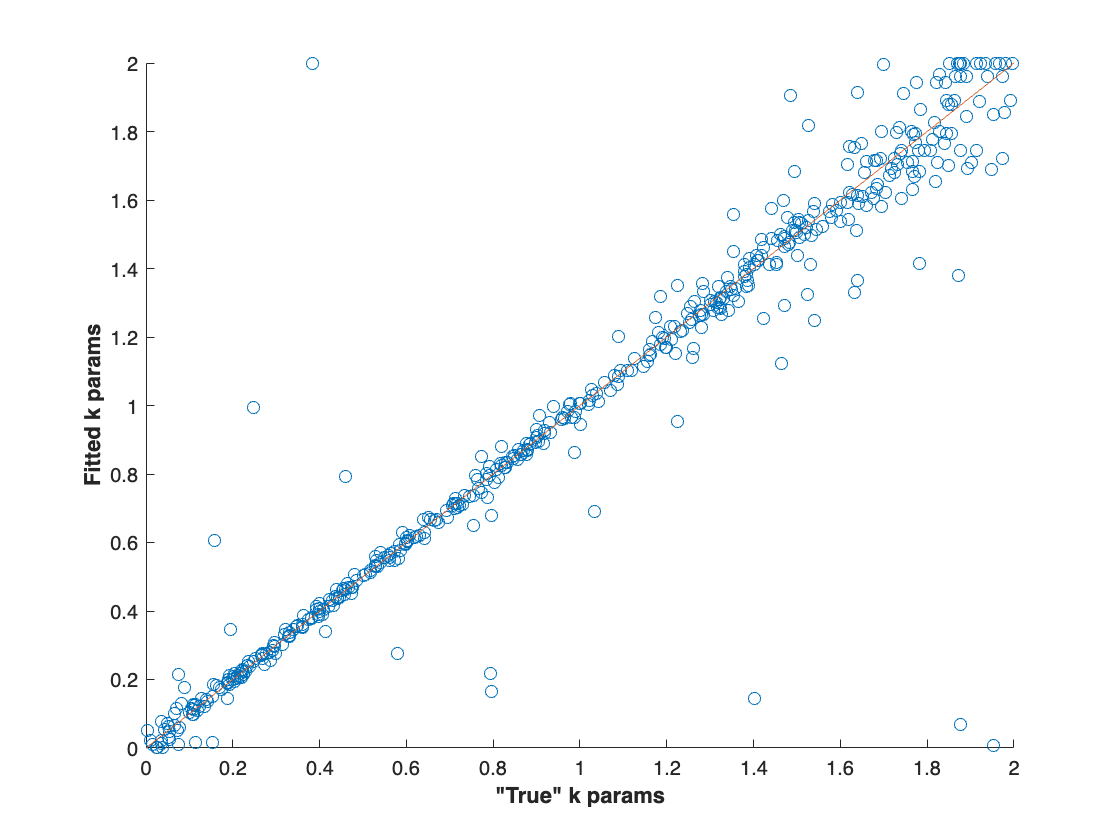

nsims = 500; %number of "participants" to simulate

% Generate "true" k and beta values from random distribution
sim_k_values    = rand(1, nsims) * ub(1);
sim_beta_values = rand(1, nsims) * ub(2);

fit_params = zeros(nsims, 2); %(preallocate array to improve speed)

% Loop through each combination of parameters
for isim = 1:nsims
    k_param_true = sim_k_values(isim);
    beta_param_true = sim_beta_values(isim);

    % Generate simulated choices based on this combination of parameters   
    reward = repmat(2:4, 1, 8*50)';
    effort = repmat(repelem(2:5, 3), 1, 2*50)'; % repeat same 12 trials for each recipient
    recipient = repelem(["food", "climate"], 12*50)';

    % Compute subjective value of "work" option
    SV = reward - (effort .* k_param_true);
    
    % Calculate probabilities of choosing work option
    prob = exp(SV .* beta_param_true) ./ (exp(SV .* beta_param_true) + exp(1 .* beta_param_true));
    
    choices = prob > rand(length(prob), 1);
    sim_data = table(choices, reward, effort, recipient, repelem(k_param_true, length(choices), 1), repelem(beta_param_true, length(choices), 1));

    % Fit the simulated data using MLE
    inputfun = @(params) fitModel(sim_data, params);
    initial_params = rand(1, 2);
    fit_params(isim, :) = fmincon(inputfun, ...
        initial_params, [], [], [], [], ...
        lb, ub, [], ...
        fminoptions);
end
scatter(sim_k_values', fit_params(:,1)); refline(1,0); xlabel('"True" k params', 'fontweight', 'bold'); ylabel('Fitted k params', 'fontweight', 'bold');

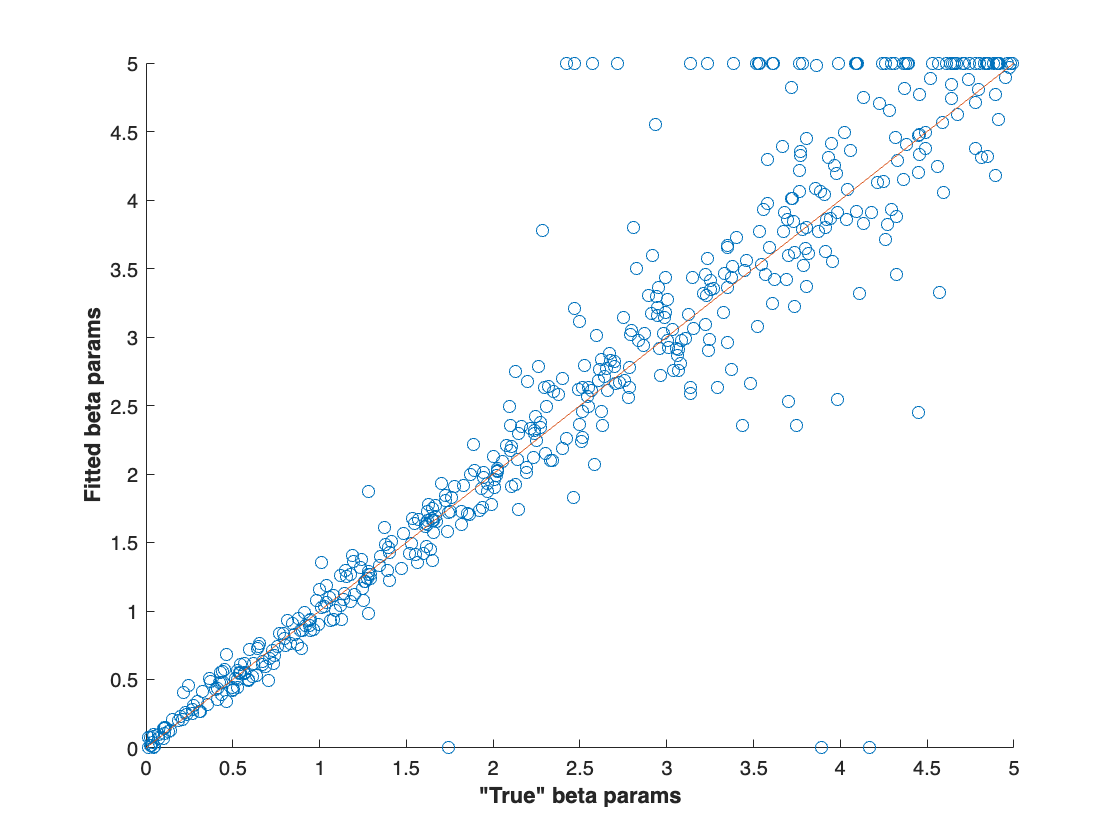

scatter(sim_beta_values', fit_params(:,2)); refline(1,0); xlabel('"True" beta params', 'fontweight', 'bold'); ylabel('Fitted beta params', 'fontweight', 'bold');

## Fitting different types of models

Simulate data using a parabolic model. Will use this data to fit different types of models (linear, parabolic, hyperbolic) to see which type of model best describes the data (i.e., the one that best minimises the log-likelihood).

model_ids = {
    'one_k_one_beta_linear', ...
    'one_k_one_beta_para', ...
    'one_k_one_beta_hyper'
    };

nsims = 500;
sim_data_para = cell(1, nsims);

true_k_params = rand(1, nsims) * 2;
true_beta_params = rand(1, nsims) * 3;

for i = 1:nsims
    sim_data_para{i} = simulateData([true_k_params(i), true_beta_params(i)],...
        'one_k_one_beta_para');
end

### Fit a linear model


$$SV = R - (E*k)$$


fit_linear = zeros(nsims, 2);
negLL_linear = zeros(nsims, 1);

model_id = 'one_k_one_beta_linear';
lb = [0, 0];
ub = [2, 5];

for isubj = 1:length(sim_data_para)

    subj_data = sim_data_para{isubj};

    % Fit the data using MLE
    inputfun = @(params) fitModel(subj_data, params, model_id);
    initial_params = rand(1, 2);
    [fit_linear(isubj, :), negLL_linear(isubj)] = fmincon(inputfun, ...
        initial_params, [], [], [], [], ...
        lb, ub, [], ...
        fminoptions);
end

fprintf('Minimised log-likelihood: %f', sum(negLL_linear));

Minimised log-likelihood: 1859.197753

Fitted k parameter vs. "True" k parameter

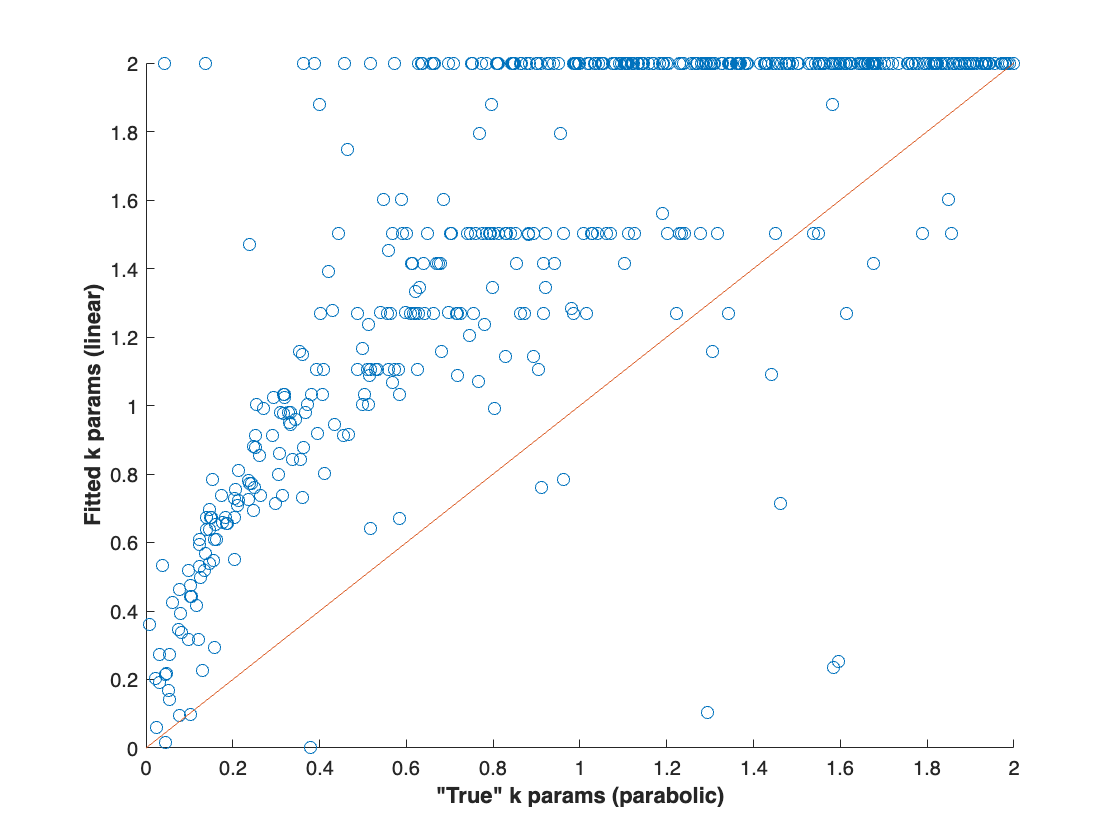

scatter(true_k_params', fit_linear(:,1));
refline(1,0); xlabel('"True" k params (parabolic)', 'fontweight', 'bold'); ylabel('Fitted k params (linear)', 'fontweight', 'bold');

Fitted beta parameter vs. "True" beta parameter

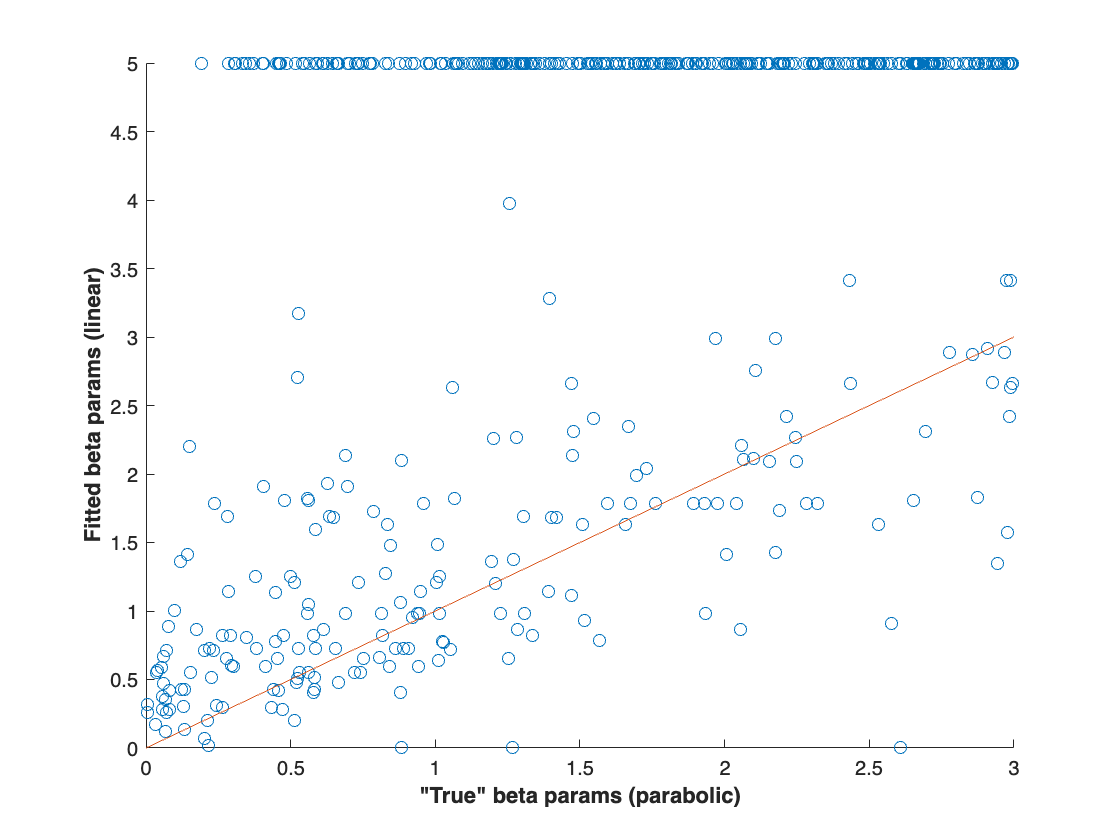

scatter(true_beta_params', fit_linear(:,2));
refline(1,0); xlabel('"True" beta params (parabolic)', 'fontweight', 'bold'); ylabel('Fitted beta params (linear)', 'fontweight', 'bold');

### Fit a parabolic model


$$SV = R - (E^2*k)$$


fit_para = zeros(nsims, 2);
negLL_para = zeros(nsims, 1);

model_id = 'one_k_one_beta_para';
lb = [0, 0];
ub = [2, 5];

for isubj = 1:length(sim_data_para)

    subj_data = sim_data_para{isubj};

    % Fit the data using MLE
    inputfun = @(params) fitModel(subj_data, params, model_id);
    initial_params = rand(1, 2);
    [fit_para(isubj, :), negLL_para(isubj)] = fmincon(inputfun, ...
        initial_params, [], [], [], [], ...
        lb, ub, [], ...
        fminoptions);
end

fprintf('Minimised log-likelihood: %f', sum(negLL_para));

Minimised log-likelihood: 1642.768096

Fitted k parameter vs. "True" k parameter

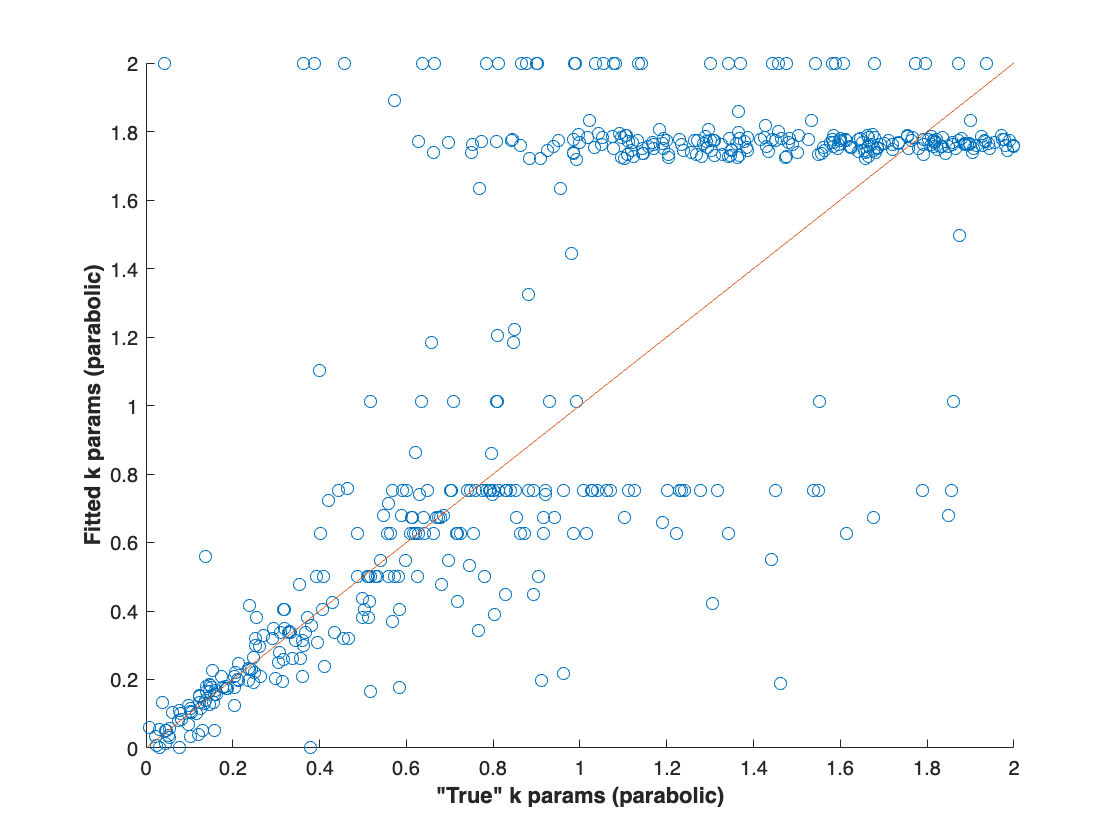

scatter(true_k_params', fit_para(:,1));
refline(1,0); xlabel('"True" k params (parabolic)', 'fontweight', 'bold'); ylabel('Fitted k params (parabolic)', 'fontweight', 'bold');

#### Things to think about: 

Why are 'k' values above 1 not recovered well here? 

What happens to SV and the softmax output at higher values of k?

How would this affect the output of simulateData()?

[Optional] Try simulating data with a max "true" k of 1. How does this affect the models ability to recover the parameter?

Fitted beta parameter vs. "True" beta parameter

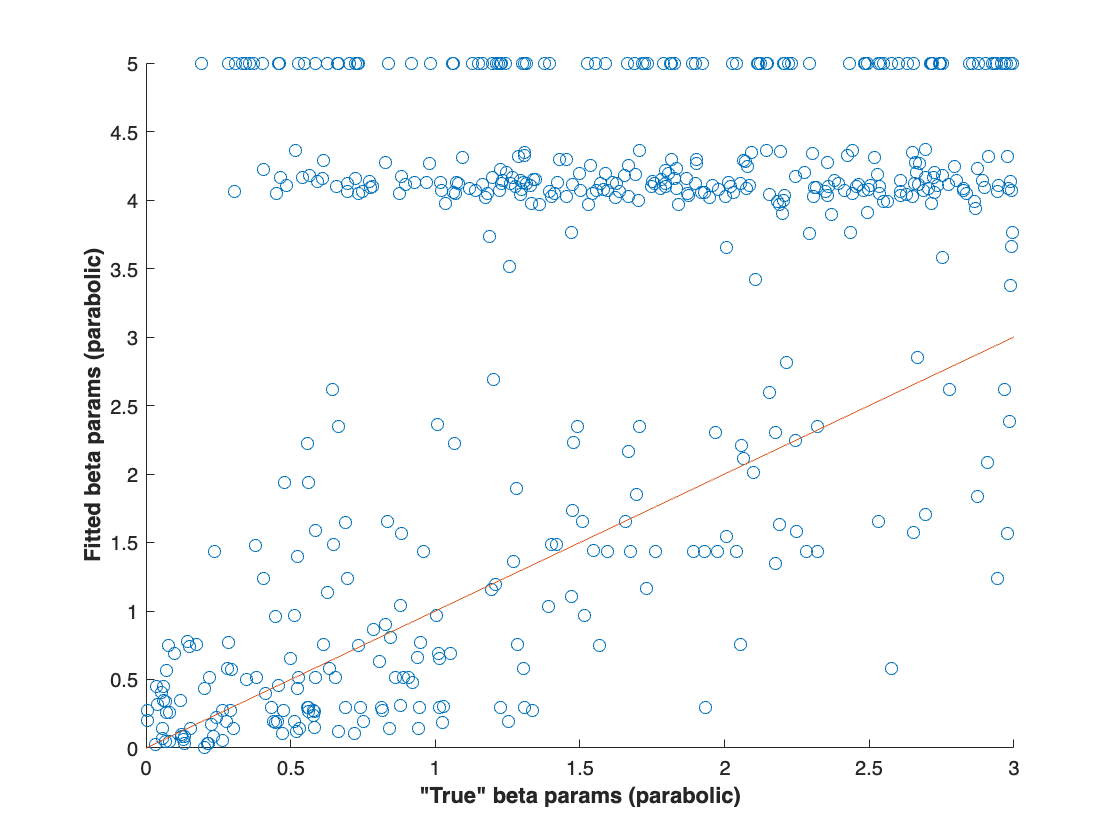

scatter(true_beta_params', fit_para(:,2));
refline(1,0); xlabel('"True" beta params (parabolic)', 'fontweight', 'bold'); ylabel('Fitted beta params (parabolic)', 'fontweight', 'bold');

### Fit a hyperbolic model


$$\frac{R}{1 + (E*k)}$$


fit_hyper = zeros(nsims, 2);
negLL_hyper = zeros(nsims, 1);

model_id = 'one_k_one_beta_hyper';
lb = [0, 0];
ub = [2, 5];

for isubj = 1:length(sim_data_para)

    subj_data = sim_data_para{isubj};

    % Fit the data using MLE
    inputfun = @(params) fitModel(subj_data, params, model_id);
    initial_params = rand(1, 2);
    [fit_hyper(isubj, :), negLL_hyper(isubj)] = fmincon(inputfun, ...
        initial_params, [], [], [], [], ...
        lb, ub, [], ...
        fminoptions);
end

fprintf('Minimised log-likelihood: %f', sum(negLL_hyper));

Minimised log-likelihood: 2499.609865

Fitted k parameter vs. "True" k parameter

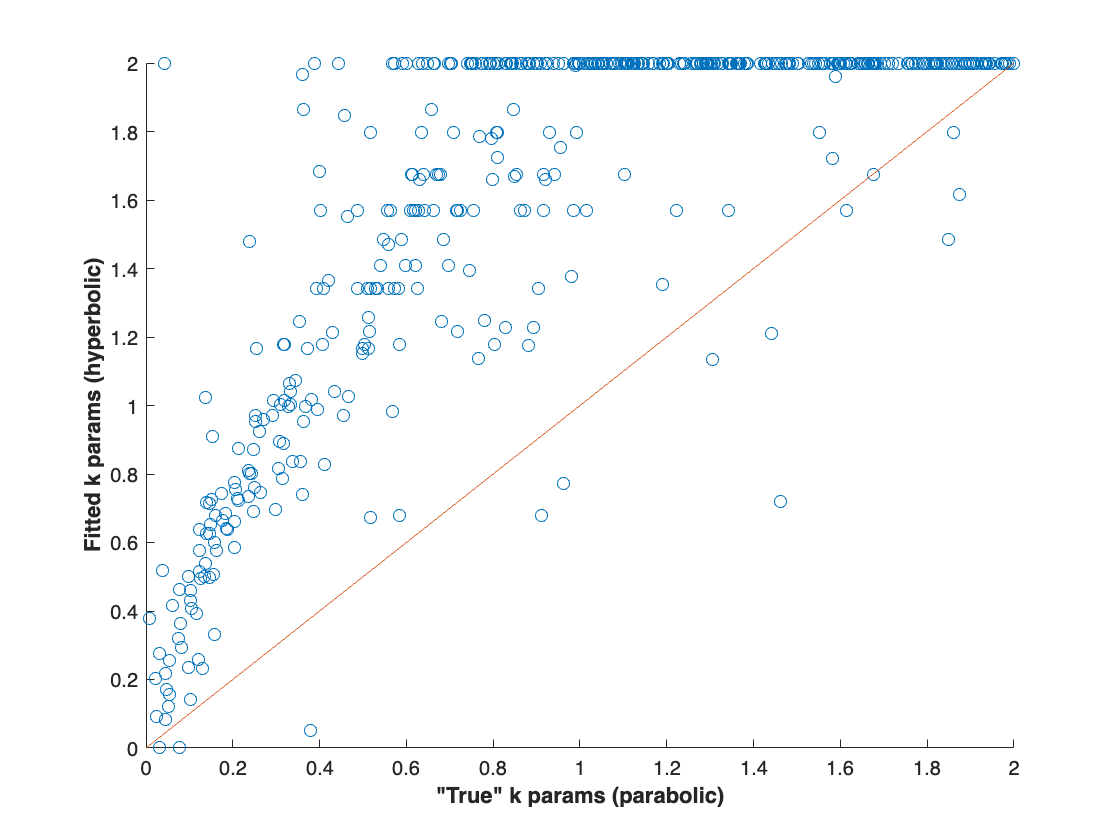

scatter(true_k_params', fit_hyper(:,1));
refline(1,0); xlabel('"True" k params (parabolic)', 'fontweight', 'bold'); ylabel('Fitted k params (hyperbolic)', 'fontweight', 'bold');

Fitted beta parameter vs. "True" beta parameter

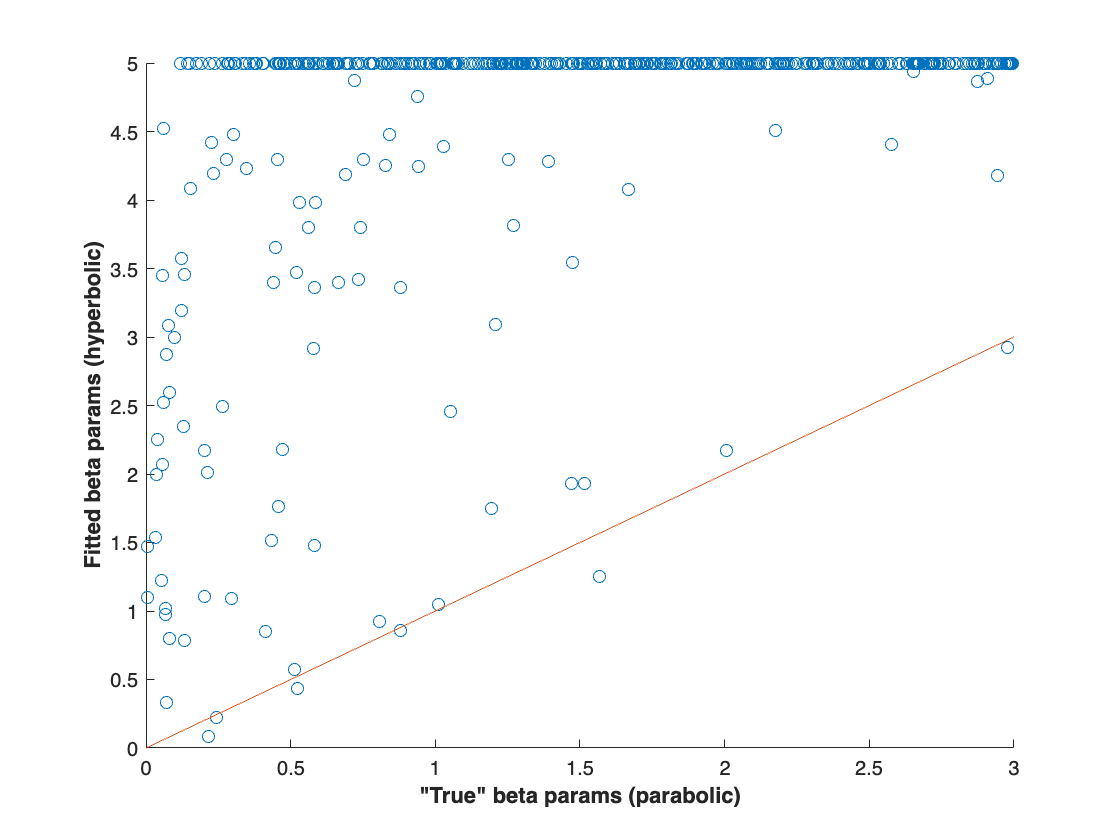

scatter(true_beta_params', fit_hyper(:,2));
refline(1,0); xlabel('"True" beta params (parabolic)', 'fontweight', 'bold'); ylabel('Fitted beta params (hyperbolic)', 'fontweight', 'bold');

## Calculate AIC/BIC to compare models

### Compare Log-Likelihoods

negLL_table = table(sum(negLL_linear), sum(negLL_para), sum(negLL_hyper), 'VariableNames', ["Linear", "Parabolic", "Hyperbolic"]);
round(negLL_table)

ans = 1×3 table
    Linear    Parabolic    Hyperbolic
    ______    _________    __________

     1859       1643          2500   


### Calculate AIC


$$AIC = -2*LL + 2*numParam$$


numParam = 2; % 1 k, 1 beta parameter

aic_linear = -2 .* (-negLL_linear) + 2 * numParam;
aic_para   = -2 .* (-negLL_para)   + 2 * numParam;
aic_hyper  = -2 .* (-negLL_hyper)  + 2 * numParam;

Note: the negLL parameter is actually the log-likelihood with its sign flipped to make it positive (to help the fmin function minimise the LL). Here we flip the sign back to get the actual log-likelihood (which confusingly, is a negative number).

aic_table = table(sum(aic_linear), sum(aic_para), sum(aic_hyper), 'VariableNames', ["Linear", "Parabolic", "Hyperbolic"]);
round(aic_table)

ans = 1×3 table
    Linear    Parabolic    Hyperbolic
    ______    _________    __________

     5718       5286          6999   


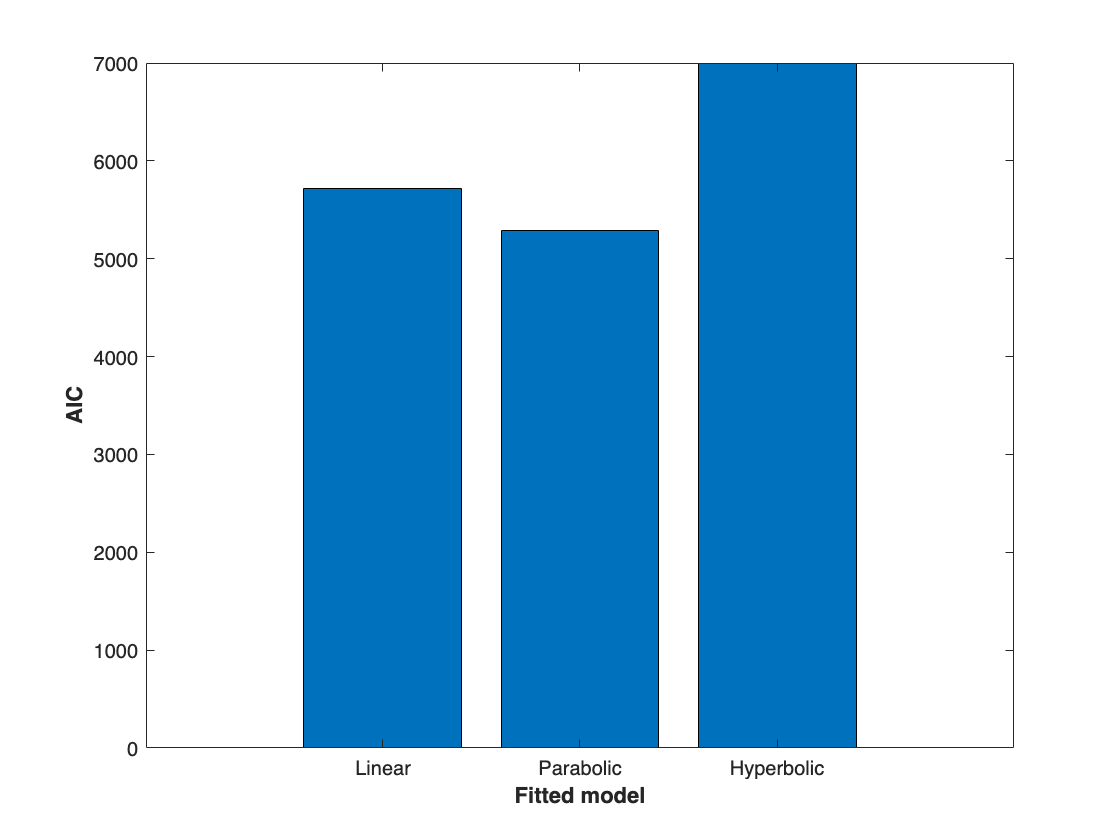

bar(1:3,[sum(aic_linear), sum(aic_para), sum(aic_hyper)]);
set(gca, 'xticklabel', ["Linear", "Parabolic", "Hyperbolic"]); xlabel('Fitted model', 'fontweight', 'bold'); ylabel('AIC', 'fontweight', 'bold');

### Calculate BIC


$$BIC = -2*LL + log(numObs)*numParam$$


numParam = 2; % 1 k, 1 beta parameter
numObs = height(subj_data); % 24, number of observations (trials) for each participant

bic_linear = -2 .* (-negLL_linear) + log(numObs) * numParam;
bic_para   = -2 .* (-negLL_para)   + log(numObs) * numParam;
bic_hyper  = -2 .* (-negLL_hyper)  + log(numObs) * numParam;

bic_table = table(sum(bic_linear), sum(bic_para), sum(bic_hyper), 'VariableNames', ["Linear", "Parabolic", "Hyperbolic"]);
round(bic_table)

ans = 1×3 table
    Linear    Parabolic    Hyperbolic
    ______    _________    __________

     6896       6464          8177   


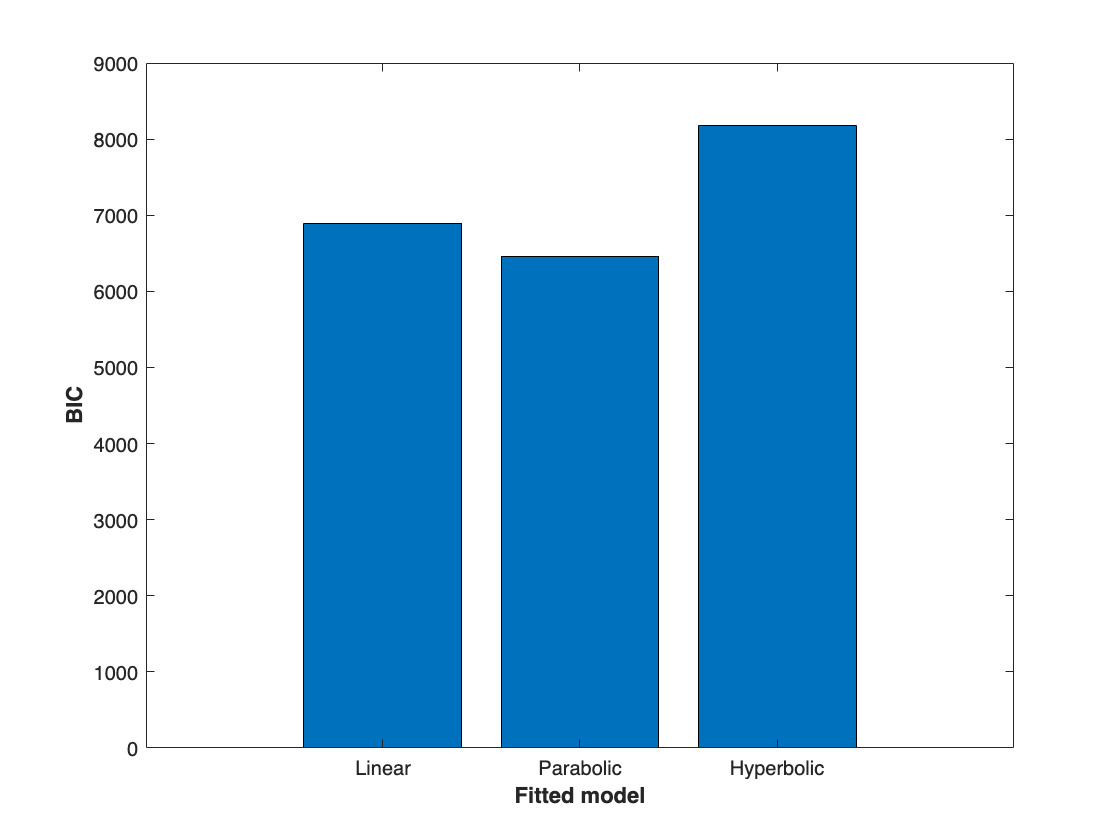

bar(1:3,[sum(bic_linear), sum(bic_para), sum(bic_hyper)]);
set(gca, 'xticklabel', ["Linear", "Parabolic", "Hyperbolic"]); xlabel('Fitted model', 'fontweight', 'bold'); ylabel('BIC', 'fontweight', 'bold');

## Fitting multiple k and beta parameters

In this example dataset, participants earn rewards for a "climate" option or a "food" option.

- We can assume that they discount effort the same for both options.

- Or we can assume they discount effort differently, depending on which options the rewards go to.

Let's simulate some data assuming #1, and compare models that test #1 vs. #2

Simulate data based on 1 k and 1 beta parameter

nsims = 100;
data_one_k_one_b_lin = cell(1, nsims);

true_k_params    = rand(1, nsims) * 2;
true_beta_params = rand(1, nsims) * 3;

for isubj = 1:nsims
    data_one_k_one_b_lin{isubj} = simulateData([true_k_params(isubj), ...
        true_beta_params(isubj)], ...
        'one_k_one_beta_linear');
end

Fit the data to a model assuming 1 k and 1 beta

model_id = 'one_k_one_beta_linear';
lb = [0, 0];
ub = [2, 5];
nparams = 2;

fit_smallmodel = zeros(nsims, nparams);
negLL_smallmodel = zeros(nsims, 1);

for isubj = 1:length(data_one_k_one_b_lin)

    subj_data = data_one_k_one_b_lin{isubj};

    % Fit the data using MLE
    inputfun = @(params) fitModel(subj_data, params, model_id);
    initial_params = rand(1, nparams);
    [fit_smallmodel(isubj, :), negLL_smallmodel(isubj)] = fmincon(inputfun, ...
        initial_params, [], [], [], [], ...
        lb, ub, [], ...
        fminoptions);
end

sumnegLL_smallmodel = sum(negLL_smallmodel);
aic_smallmodel = sum(-2 .* (-negLL_smallmodel) + 2 .* nparams);
bic_smallmodel = sum(-2 .* (-negLL_smallmodel) + log(height(subj_data)) .* nparams);

Fit the data to a model assuming 2 k and 2 beta

model_id = 'two_k_two_beta_linear';
lb = [0, 0, 0, 0];
ub = [2, 2, 5, 5];
nparams = 4;

fit_largemodel = zeros(nsims, nparams);
negLL_largemodel = zeros(nsims, 1);

for isubj = 1:length(data_one_k_one_b_lin)

    subj_data = data_one_k_one_b_lin{isubj};

    % Fit the data using MLE
    inputfun = @(params) fitModel(subj_data, params, model_id);
    initial_params = rand(1, nparams);
    [fit_largemodel(isubj, :), negLL_largemodel(isubj)] = fmincon(inputfun, ...
        initial_params, [], [], [], [], ...
        lb, ub, [], ...
        fminoptions);
end

sumnegLL_largemodel = sum(negLL_largemodel);
aic_largemodel = sum(-2 .* (-negLL_largemodel) + 2 .* nparams);
bic_largemodel = sum(-2 .* (-negLL_largemodel) + log(height(subj_data)) .* nparams);

Compare negLL, AIC, and BIC between models

negLL

disp(table(sumnegLL_smallmodel, sumnegLL_largemodel))

    sumnegLL_smallmodel    sumnegLL_largemodel
    ___________________    ___________________

          722.66                 621.49       



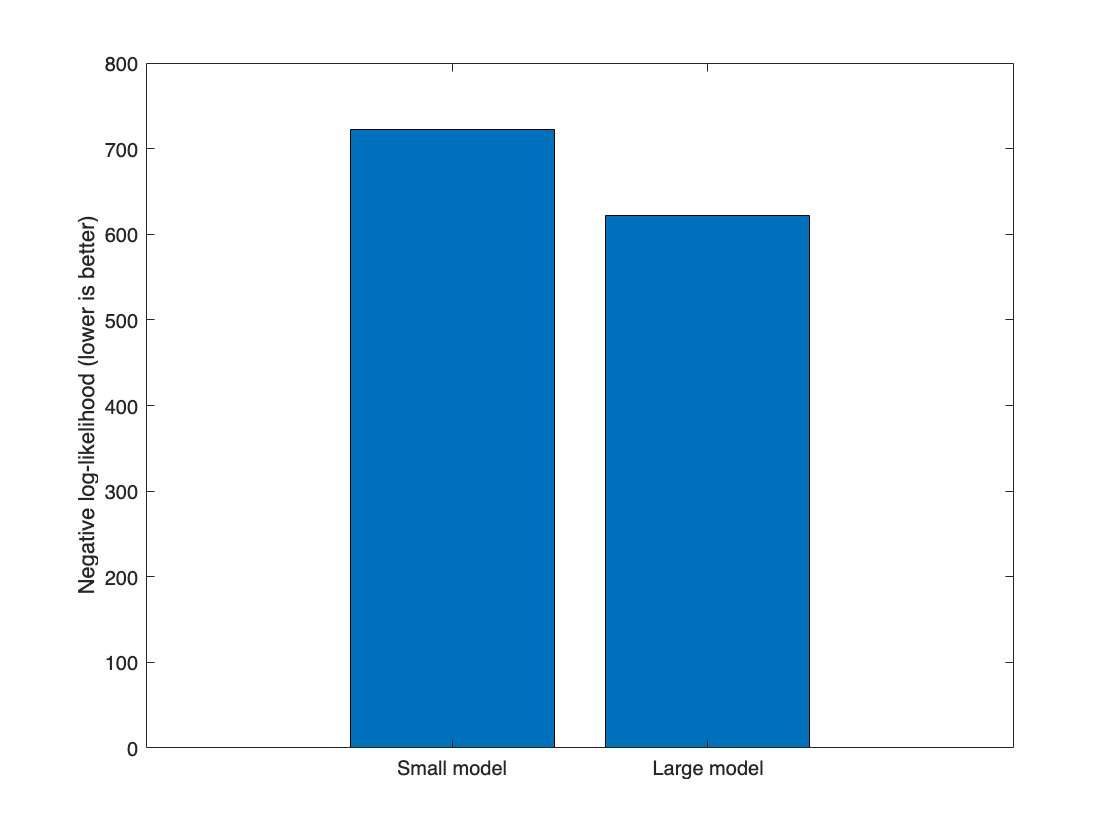

bar(1:2, [sum(negLL_smallmodel), sum(negLL_largemodel)]);
set(gca, 'xticklabels', ["Small model", "Large model"]); ylabel("Negative log-likelihood (lower is better)");

AIC

disp(table(aic_smallmodel, aic_largemodel))

    aic_smallmodel    aic_largemodel
    ______________    ______________

        1845.3             2043     



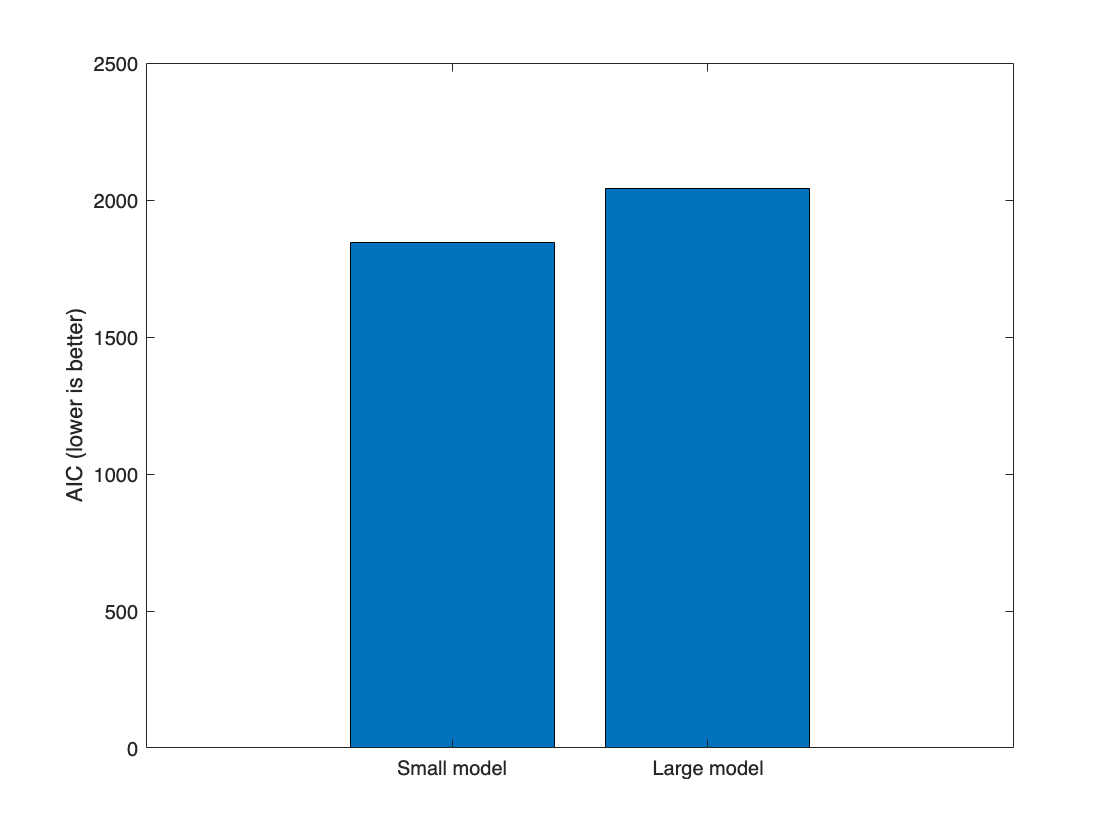

bar(1:2, [aic_smallmodel, aic_largemodel]);
set(gca, 'xticklabels', ["Small model", "Large model"]); ylabel("AIC (lower is better)");

BIC

disp(table(bic_smallmodel, bic_largemodel))

    bic_smallmodel    bic_largemodel
    ______________    ______________

        2080.9            2514.2    



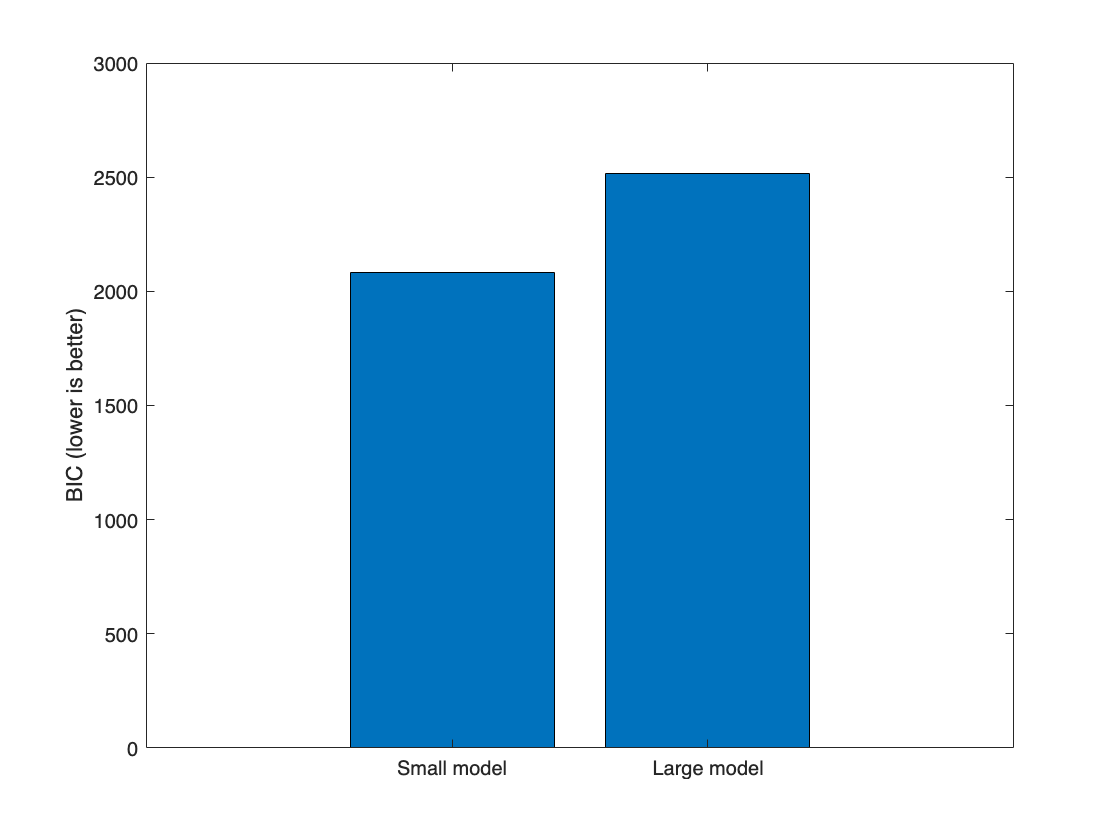

bar(1:2, [bic_smallmodel, bic_largemodel]);
set(gca, 'xticklabels', ["Small model", "Large model"]); ylabel("BIC (lower is better)");

## Functions

function negLL = fitModel(data, params, model_id)
% Fits parameters to model and calculates softmax and negative log-likelihood

% Note: including this arguments block helps make your code robust, but may slow down fitting when using fmincon
% Can comment out for real data analyses, after your scripts have been written.
arguments
    data table
    params (1, :) double
    model_id string = 'one_k_one_beta_linear' % defaults to linear if model_id not specified
end

% Get reward, effort, and choices from data
reward = data.reward;
effort = data.effort;
choices = data.choices;
recipient = data.recipient;

% Assign k parameter values
if contains(model_id, 'one_k')
    n_ks = 1;
    k_param = repelem(params(1), length(recipient), 1);
elseif contains(model_id, 'two_k')
    n_ks = 2;
    k_param = (recipient=="food").*params(1) + (recipient=="climate").*params(2);
else
    error('k parameters in %s misspecified', model_id);
end

% Assign beta parameter values
if contains(model_id, 'one_beta')
    beta_param = repelem(params(1 + n_ks), length(recipient), 1);
elseif contains(model_id, 'two_beta')
    beta_param = (recipient=="food").*params(1 + n_ks) + (recipient=="climate").*params(2 + n_ks);
else
    error('beta parameters in %s misspecified', model_id);
end

% Compute subjective value of "work" option
% (Based on type of model specified by 'model_id')
if contains(model_id, 'linear')
    SV = reward - (effort .* k_param);
elseif contains(model_id, 'para')
    SV = reward - ((effort.^2) .* k_param);
elseif contains(model_id, 'hyper')
    SV = reward ./ (1 + (effort .* k_param));
else
    error("Model ID: %s is incorrectly specified.", model_id)
end

% Calculate probabilities of choosing work option
prob = exp(SV .* beta_param) ./ (exp(SV .* beta_param) + exp(1 .* beta_param));

% Probability of choosing "rest" option
prob(~choices) = 1 - prob(~choices);

% Convert probabilities to log-likelihoods
% Note: the LogSumExp function can be used to calculate log-likelihoods in a more numerically stable way (https://en.wikipedia.org/wiki/LogSumExp)
LL = log(prob);
negLL = -sum(LL); %sum LL together and flip sign to make values positive (for fmin minimizing function)

end


function data = simulateData(true_params, model_id)
% Generates simulated data for a participant based on the "true" parameters supplied

arguments
    true_params (1, :) double
    model_id string = 'one_k_one_beta_linear' % defaults to linear if model_id not specified
end

reward = repmat(2:4, 1, 8)';
effort = repmat(repelem(2:5, 3), 1, 2)'; % repeat same 12 trials for each recipient
recipient = repelem(["food", "climate"], 12)';

% Define k parameters
if contains(model_id, 'one_k')
    n_ks = 1;
    k_param_true = repelem(true_params(1), length(recipient), 1);
elseif contains(model_id, 'two_k')
    n_ks = 2;
    k_param_true = (recipient=="food").*true_params(1) + (recipient=="climate").*true_params(2);
else
    error('k parameters in %s misspecified', model_id);
end

% Define beta parameters
if contains(model_id, 'one_beta')
    beta_param_true = repelem(true_params(1 + n_ks), length(recipient), 1);
elseif contains(model_id, 'two_beta')
    beta_param_true = (recipient=="food").*true_params(1 + n_ks) + (recipient=="climate").*true_params(2 + n_ks);
else
    error('beta parameters in %s misspecified', model_id);
end

% Compute subjective value of "work" option
% (Based on type of model specified by 'model_id')
if contains(model_id, 'linear')
    SV = reward - (effort .* k_param_true);
elseif contains(model_id, 'para')
    SV = reward - ((effort.^2) .* k_param_true);
elseif contains(model_id, 'hyper')
    SV = reward ./ (1 + (effort .* k_param_true));
else
    error("Model ID: %s is incorrectly specified.", model_id)
end

% Calculate probabilities of choosing work option
% (calculates probability for each row of matrix (i.e., trial) based on SV and baseline values)
prob = exp(SV .* beta_param_true) ./ (exp(SV .* beta_param_true) + exp(1 .* beta_param_true));

choices = prob > rand(length(prob), 1);

data = table(choices, reward, effort, recipient);
data.k_param_true = k_param_true;
data.beta_param_true = beta_param_true;

end